## 2D Plot $f\left(x\right)=x+\frac{1}{x}$ function

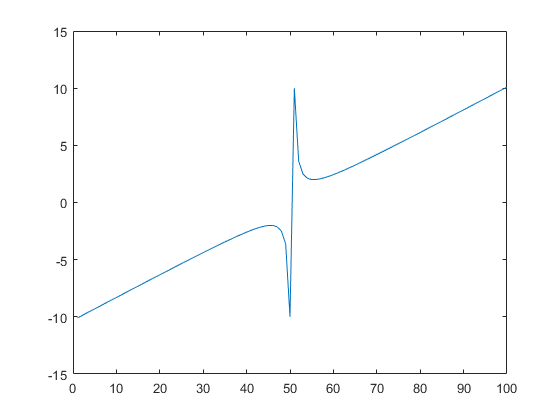

x = linspace(-10,10,100);

myFunc2 = x + x.^-1;

plot(myFunc2)

## Plot the 3D surface of the function 

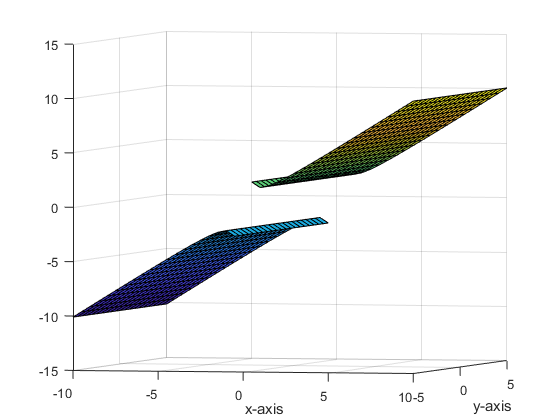

[X,Y] = meshgrid(-10:0.5:10,-5:0.5:5);

myFunc2surface = X + X.^-1;

surf(X, Y, myFunc2surface);

xlabel('x-axis')
ylabel('y-axis')

The first order derivative of $f(x) = x + \frac{1}{x}$ is $f'(x) = 1 - \frac{1}{x^2}$ and the stationary points are $x = 1$ and 


$$x = -1.$$


The second order derivative is $f''(x) = \frac{2}{x^3}$, and $f''(x = 1) = 2 > 0 $ **strict** local minimum, $f''(x = -1) = -2 < 0$ **strict** local maximum. 

At the stationary points, the function values are $f(x = -1) = -2 $ and $f(x = 1) = 2$.

The **global minimum** of the function is $-\infty$ at $x = -\epsilon$, which is **not** a stationary point. 

Here, $\epsilon>0$ is a very small positive number. 

## Bisection Search Method for the function $x + \frac{1}{x}$ in the range $x \in [0.1, 10]$ with precision $\epsilon = 0.01$.

epsilon = 0.001;
a = 0.1;
b = 10;

while (b - a) > epsilon
    x = (a + b) / 2;
    if evaluateFunc(x) >= evaluateFunc(x + epsilon)
        a = x
    else b = x
    end
end

b = 5.0500

b = 2.5750

b = 1.3375

a = 0.7188

b = 1.0281

a = 0.8734

a = 0.9508

a = 0.9895

b = 1.0088

a = 0.9991

b = 1.0040

b = 1.0015

b = 1.0003

b = 0.9997

(a + b) / 2

ans = 0.9994

function evalFunc = evaluateFunc(x)
    evalFunc = x + 1/ x; 
end